# Ocean-Groundwatwer interaction

clear, close all, clc
set_demo_defaults

Consider the relation between Mars' putative ocean and its global groundwater table. If the total water volume, $V$, on Mars is fixed, then changes in groundwater volume, $V_\mathrm{G}$, must affect the ocean volume, $V_\mathrm{O}$, because

$V = V_\mathrm{G}+V_\mathrm{O}$= constant.

This implies that the ocean level is coupled to the elevation of the groundwater table, which introduces an additional feedback as shown below. If the groundwater table rises due to increased precipitation then sea-level must fall, which in-turn affects the groundwater table.

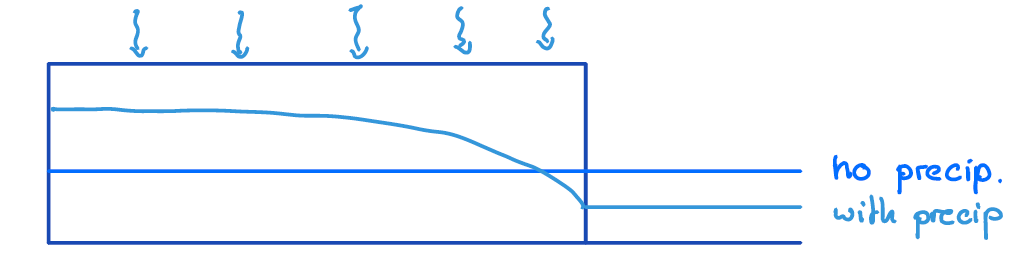f If $h$ is the head, $\phi$ is the porosity and $l$ is the length of the aquifer, then volume of groundwater is given by

$V_\mathrm{G}=\phi\int_0^l h(x) \mathrm{d}x$.

If $w$ is the width of the ocean and $h_o = h(l)$ is sea-level the ocean volume is

$V_\mathrm{O} = wh_o$.

Here all $V$'s are volumes per unit area. As such the sea-level is linked to goundwater table as

$h(l) = \frac{V}{w} - \frac{\phi}{w} \int_0^l h(x) \mathrm{d}x$.

In the absence of precipitation $h(x) = h_o$, and we have from mass balance that 


$$h_o = \frac{V}{\phi l + w}$$


which we refer to as the *reference head*.

### Governing equations

#### Dimensional equations

Consider the following steady, linear, unconfied aquifer:

PDE: $-\nabla\cdot\left[K h\nabla h\right] = q_p$ on $x\in\left[0,\,l\right]$

BC's: $\left.\mathbf{q}\cdot\hat{\mathbf{n}}\right|_0=0$ and $h(l) = \frac{V}{w} - \frac{\phi}{w} \int_0^l h(x) \mathrm{d}x$

Here the global water mass balance provides an unusual boundary condition, where the head on the boundary is related to the integral of the head itself.

#### Dimensionless equations

We choose the length of the aquifer, $l$, and the reference water level, $h_o$, as characteristic scales and define the dimensionless variables $x'=x/l$ and $h'=h/h_o$. The dimensionless governing equations are given by

PDE: $-\nabla\cdot\left[h'\nabla h\right] = \mathrm{Pr}$ and $x'\in\left[0,\,1\right]$

BC's:  $\left.\mathbf{q}'\cdot\hat{\mathbf{n}}\right|_0=0$ and $h'(1) =1+ \frac{1}{\mathrm{Ca}}\left(1 - \int_0^1 h'(x') \mathrm{d}x'\right)$

where we have two dimensionless governing parameters

Precipitation number: $\mathrm{Pr}=\frac{h_p}{h_o} = \frac{q_p l^2(\phi l+w)}{KV}\geq0$ (rise in $h$ due to precipitation, relative to reference head)

Capacity number: $Ca = \left.\frac{V_\mathrm{O}}{V_\mathrm{G}}\right|_{\mathrm{Pr}=0}= \frac{w}{\phi l}>0$ (volume of sea water relative to groundwater in absence of precipitation)

### Analytical solution

#### Interface shape

We solve this problem by first assuming the head on the boundary to be given paramter $h'(1)=\Pi$ and solving for the shape of the interface $h'(x';\mathrm{Pr},\Pi)$, as function of the two paramters $\mathrm{Pr}$ and $\Pi$. Integrating twice and using the boundary conditions we have the solution


$$h' = \sqrt{\Pi^2+\mathrm{Pr}(1-{x'}^2)}$$


hD = @(xD,Pi,Pr,Ca) sqrt(Pi^2+Pr*(1-xD.^2));

#### Mass-balance constraint

Now we need to determine $\Pi$ from mass balance,  by solving the boundary condition


$$\Pi =1+ \frac{1}{\mathrm{Ca}}\left(1 - \int_0^1  \sqrt{\Pi^2+\mathrm{Pr}(1-{x'}^2)}\mathrm{d}x'\right)$$


for $\Pi$! The integral of the dimensionless head is given by


$$H(\mathrm{Pr},\Pi) = \frac{\sqrt{\mathrm{Pr}}(\mathrm{Pr}+\Pi^2)\arcsin\sqrt{\frac{\mathrm{Pr}}{\mathrm{Pr}+\Pi^2}}+\mathrm{Pr}\Pi }{2\mathrm{Pr}}$$
 

HD = @(Pi,Pr) (sqrt(Pr).*(Pr+Pi.^2).*asin(sqrt(Pr./(Pr+Pi.^2)))+Pi.*Pr)./(2*Pr);

The figure shows the variation of groundwater volume as function of the two dimensionless input paramters $\mathrm{Pr}$ and $\Pi$. For $\mathrm{Pr}>0$ only solutions with $H>1$ are possible, because the groundwater volume must increase with precipitation over the reference. As such we can identify feasible and infeasible regions in parameter space.

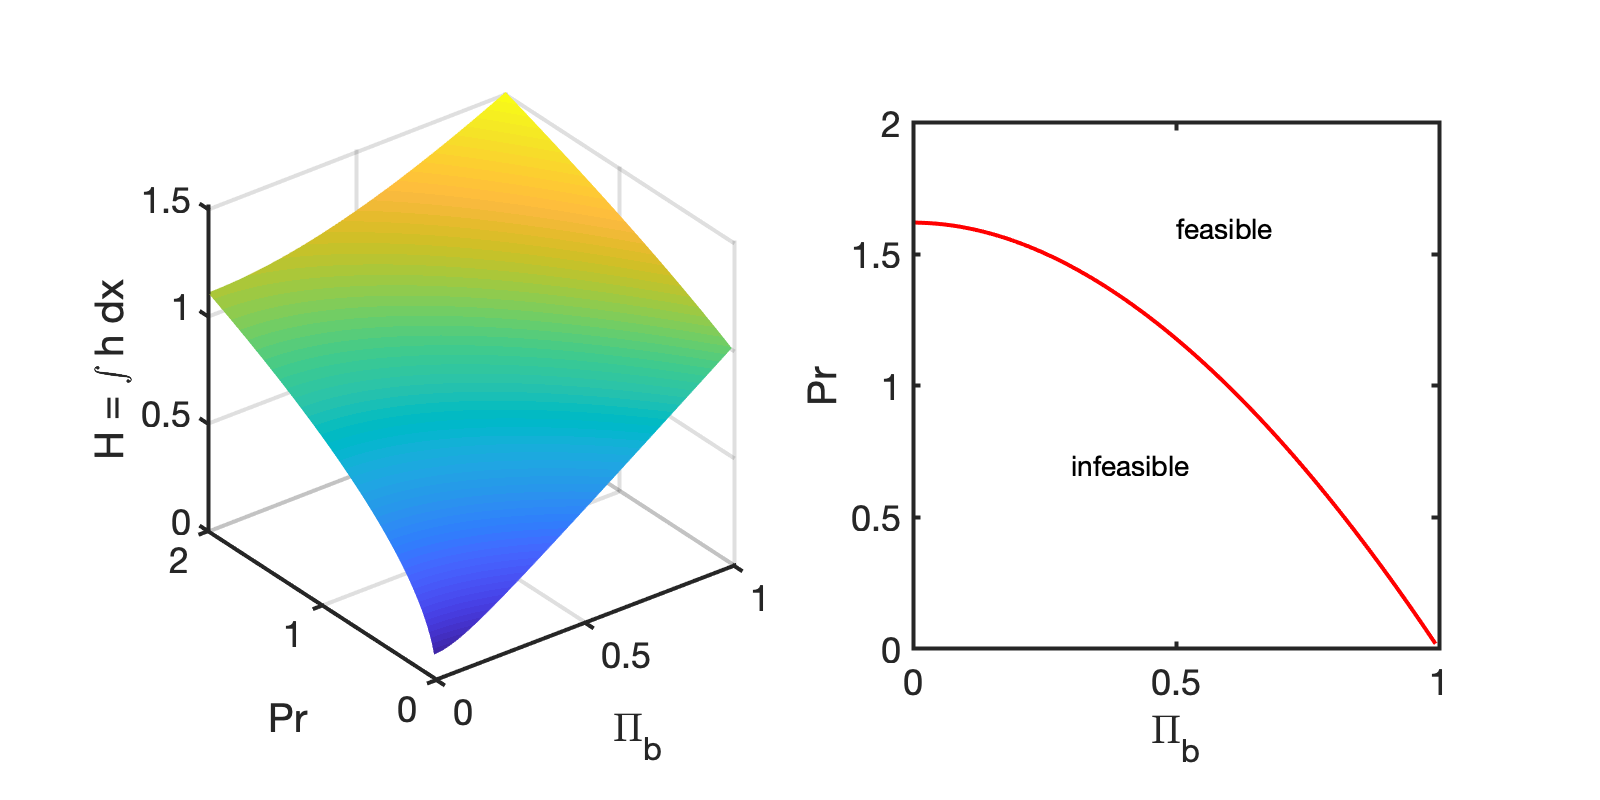

Pi_vec = linspace(0,1,100);
Pr_vec = linspace(0,2,100);
[PI,PR] = meshgrid(Pi_vec,Pr_vec);

HD_feasible = HD(PI,PR);
HD_feasible(HD(PI,PR)<1) = NaN;
PI_feasible = PI;
PI_feasible(HD(PI,PR)<1) = NaN;
OBJ = @(Ca) 1+1/Ca*(1-HD_feasible) - PI_feasible;

figure('position',[10 10 800 400])
subplot 121
surf(PI,PR,HD(PI,PR)), shading interp
xlabel('\Pi_b')
ylabel('Pr')
zlabel 'H = \int h dx'
pbaspect([1 1 1])

subplot 122
contour(PI,PR,HD(PI,PR),[1 1],'r','linewidth',2)
xlabel('\Pi_b')
ylabel('Pr')
text(.3,.7,'infeasible','FontSize',14)
text(.5,1.6,'feasible','FontSize',14)
pbaspect([1 1 1])

To determine the head at the boundary we need to solve the objective function


$$\mathrm{obj}(\mathrm{Pr}, \mathrm{Ca}) = 1+ \frac{1}{ \mathrm{Ca}} \left(1-H(\mathrm{Pr}, \Pi)\right)-\Pi$$


due to the transcendental functions in $H$ we need to solve this equation numerically. To get a sense of the behavior we can plot the zero level sets for different $\mathrm{Ca}$ in $\mathrm{Pr}\Pi$-space. The figure shows three contours for different $\mathrm{Ca}$, which shows that $\Pi$ declines faster with increasing $\mathrm{Pr}$ if $\mathrm{Ca}$ is small.

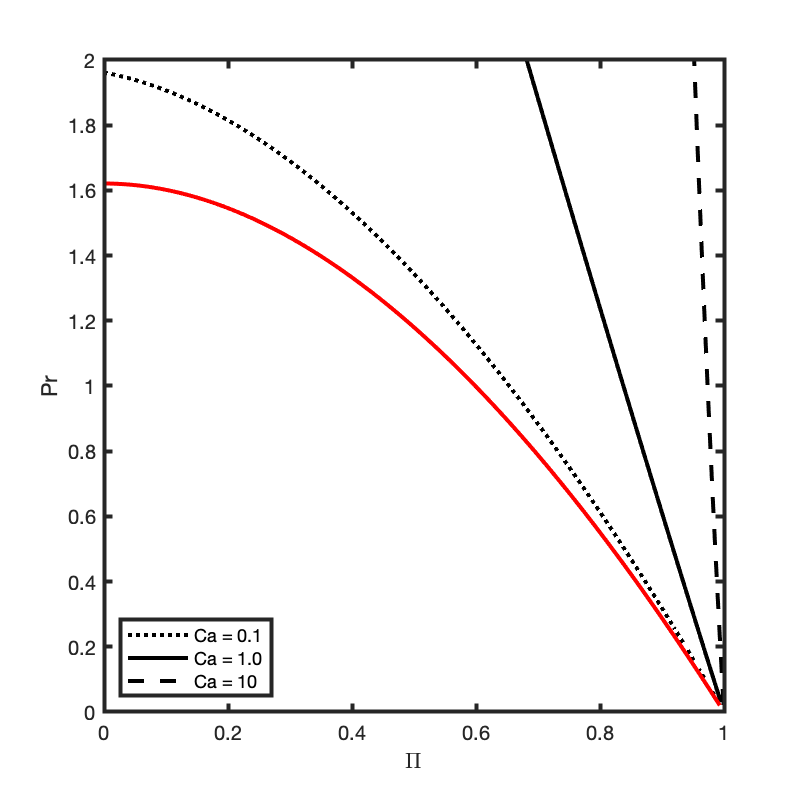

figure('position',[10 10 400 400])
contour(PI,PR,OBJ(.1),[0 0],'k:','linewidth',2), hold on
contour(PI,PR,OBJ(1),[0 0],'k','linewidth',2)
contour(PI,PR,OBJ(10),[0 0],'k--','linewidth',2)
contour(PI,PR,HD(PI,PR),[1 1],'r','linewidth',2)
legend('Ca = 0.1','Ca = 1.0','Ca = 10','location','southwest')
xlabel('\Pi','FontSize',16)
ylabel('Pr','FontSize',16)

### Solutions for Ocean-Grwoundwater interactions

#### Small ocean capacity

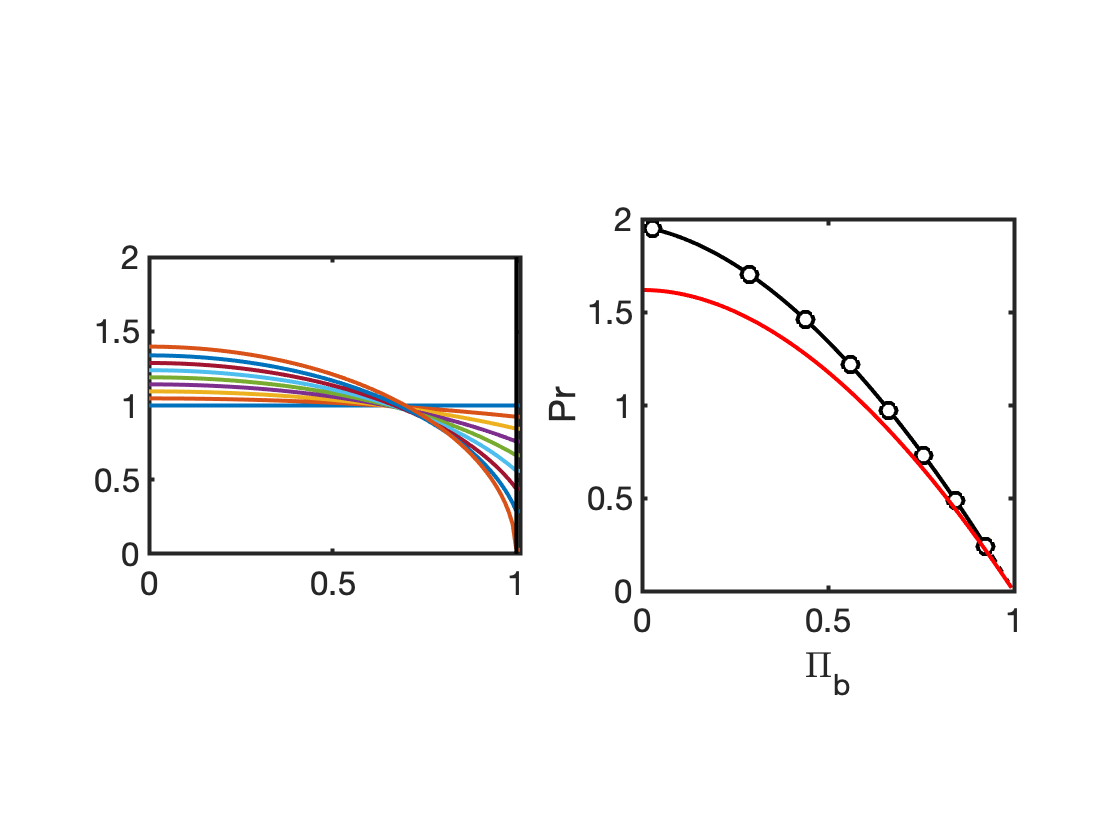

Ca = .1                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                             ;
phi = 0.1;
xD = linspace(0,1,1e2);
figure
Pr_vec = linspace(0,1.95,9); Pr_vec = Pr_vec(2:end);
subplot 121
plot([0 1+phi*Ca],[1 1]), hold on
for i = 1:length(Pr_vec)
    Pi = Pi_fun(Pr_vec(i),Ca,HD);
    Pi_vec2(i) = Pi;
    plot([xD,1+phi*Ca],[hD(xD,Pi,Pr_vec(i),Ca),Pi],'-'), hold on
end
plot([1 1],[0 2],'k-')
ylim([0 2])
pbaspect([1 .8 1])

subplot 122
contour(PI,PR,OBJ(Ca),[0 0],'k-','linewidth',2), hold on
plot(Pi_vec2,Pr_vec,'ko','markersize',8,'markerfacecolor','w')
contour(PI,PR,HD(PI,PR),[1 1],'r','linewidth',2)
xlabel('\Pi_b')
ylabel('Pr')
pbaspect([1 1 1])

#### Unit ocean capacity

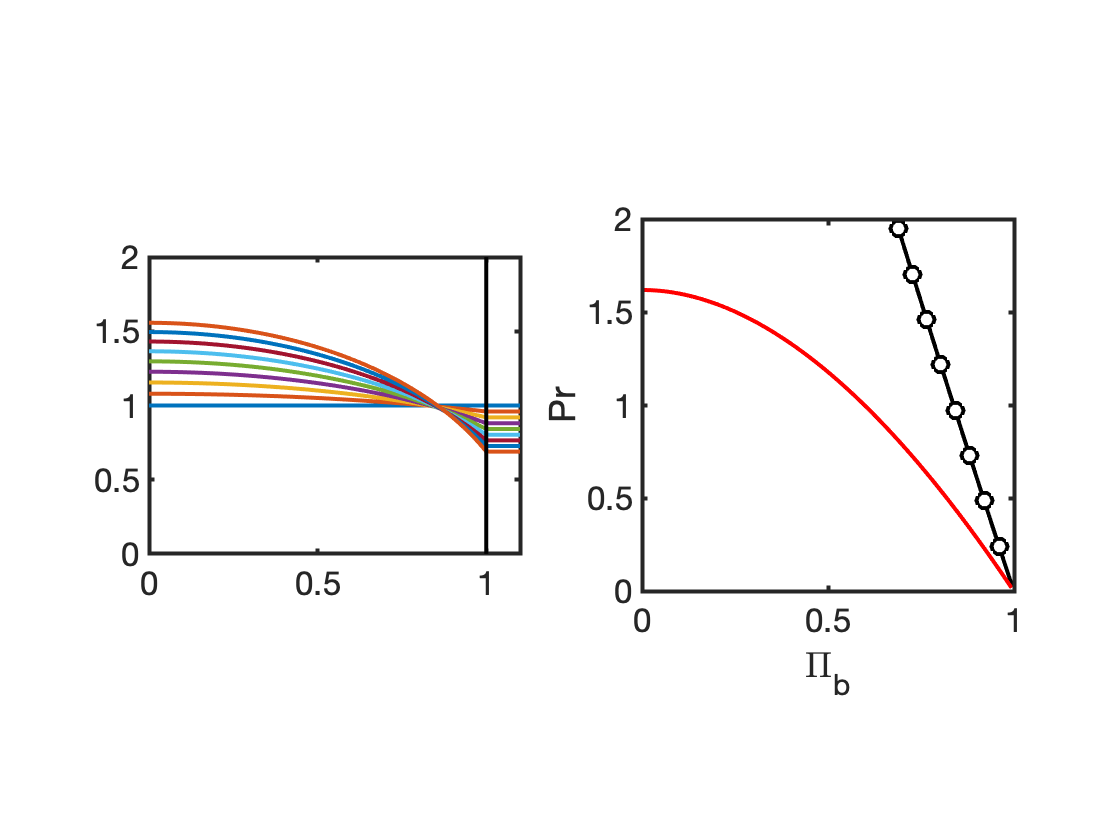

Ca = 1;                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                           ;
phi = 0.1;
xD = linspace(0,1,1e2);
figure
subplot 121
plot([0 1+phi*Ca],[1 1]), hold on
for i = 1:length(Pr_vec)
    Pi = Pi_fun(Pr_vec(i),Ca,HD);
    Pi_vec2(i) = Pi;
    plot([xD,1+phi*Ca],[hD(xD,Pi,Pr_vec(i),Ca),Pi],'-'), hold on
end
plot([1 1],[0 2],'k-')
ylim([0 2])
pbaspect([1 .8 1])

subplot 122
contour(PI,PR,OBJ(Ca),[0 0],'k-','linewidth',2), hold on
plot(Pi_vec2,Pr_vec,'ko','markersize',8,'markerfacecolor','w')
contour(PI,PR,HD(PI,PR),[1 1],'r','linewidth',2)
xlabel('\Pi_b')
ylabel('Pr')
pbaspect([1 1 1])

#### Large ocean capacity

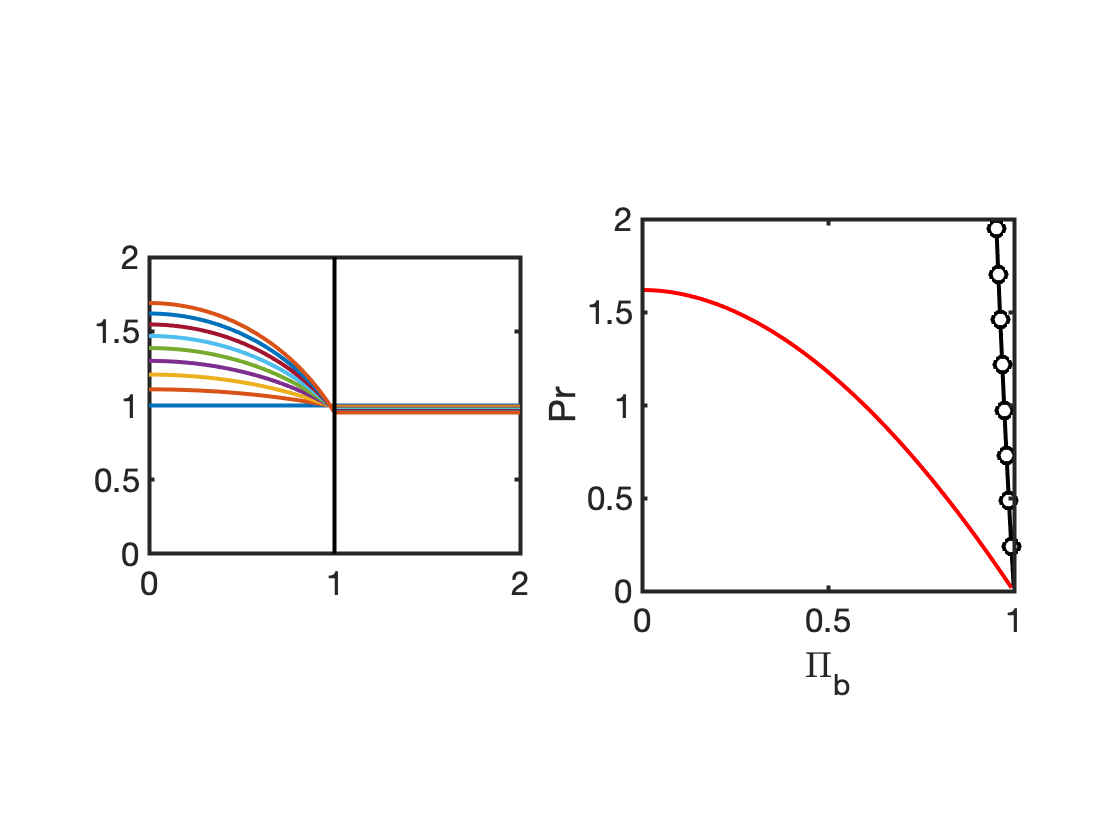

Ca = 10;                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                           ;
phi = 0.1;
xD = linspace(0,1,1e2);
figure
subplot 121
plot([0 1+phi*Ca],[1 1]), hold on
for i = 1:length(Pr_vec)
    Pi = Pi_fun(Pr_vec(i),Ca,HD);
    Pi_vec2(i) = Pi;
    plot([xD,1+phi*Ca],[hD(xD,Pi,Pr_vec(i),Ca),Pi],'-'), hold on
end
plot([1 1],[0 2],'k-')
ylim([0 2])
pbaspect([1 .8 1])

subplot 122
contour(PI,PR,OBJ(Ca),[0 0],'k-','linewidth',2), hold on
plot(Pi_vec2,Pr_vec,'ko','markersize',8,'markerfacecolor','w')
contour(PI,PR,HD(PI,PR),[1 1],'r','linewidth',2)
xlabel('\Pi_b')
ylabel('Pr')
pbaspect([1 1 1])

## Auxillary functions

function [Pi] = Pi_fun(Pr,Ca,HD)
obj = @(Pi) 1+1/Ca*(1-HD(Pi,Pr)) - Pi;
Pi_vec = linspace(0,1,100);
Pi = fzero(obj,.3);
end